# Finding a 2D mixed-mode SSM for regular dynamics of an inverted flag from experiments

In this notebook we investigate a fluid - structure interaction problem. A flexible sheet, the flag, is placed in a water tunnel. The trailing edge (with respect to the flow direction) is clamped. 

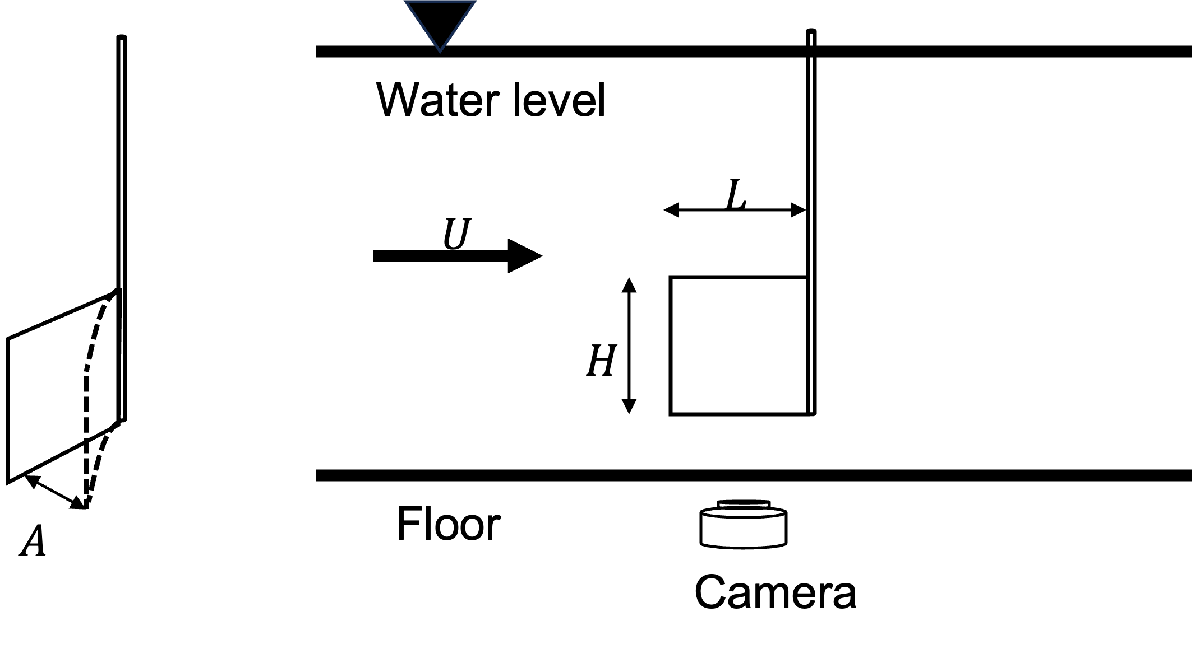

(Experiments taken in Coletti Lab: Institute of Fluid Dynamics, ETH Zurich)

The dynamics of an inverted flag exhibit different regimes as flow velocities increase in the water tunnel, leading to a decrease in the system's stiffness $K_B$. We briefly present the bifurcation diagram of an inverted flag and highlight the two states upon which our models are built: regular flapping and chaotic flapping.

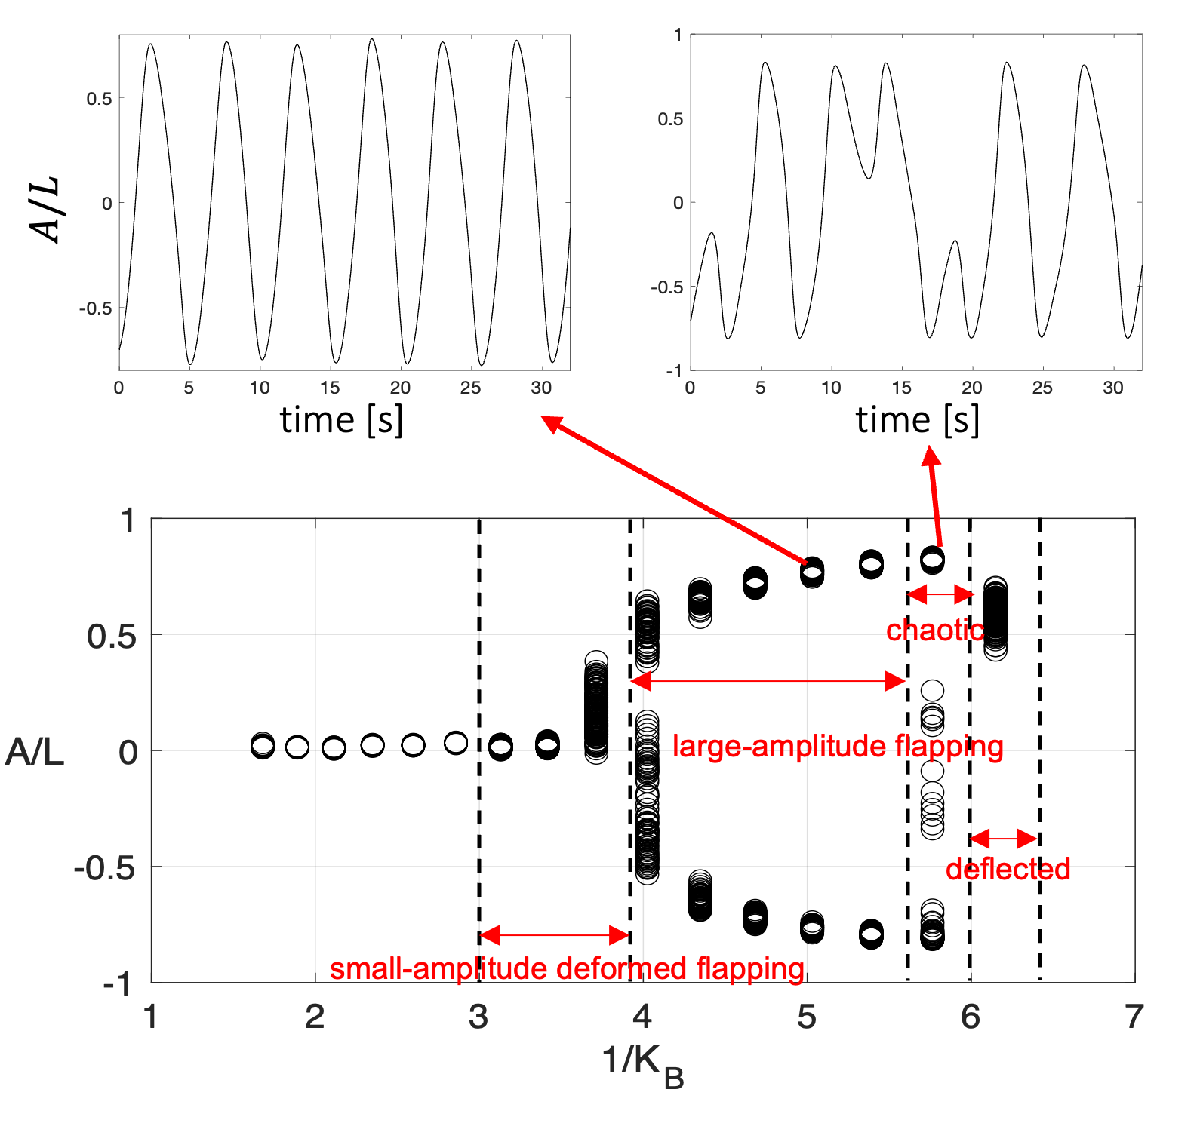

Video footage is recorded in the regime of large-amplitude flapping of the flag, which we call in short **flapping. **

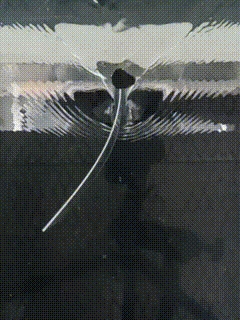

### References

[1] Z. Xu, B. Kaszás, M. Cenedese, G. Berti, F. Coletti, G. Haller, Data-driven modeling of the regular and chaotic dynamics of an inverted flag from experiments, [*J. Fluid Mech.*](https://www.cambridge.org/core/journals/journal-of-fluid-mechanics/article/datadriven-modelling-of-the-regular-and-chaotic-dynamics-of-an-inverted-flag-from-experiments/36D6DD09754069BF7EE05F9F3B50C988) (2024) 

[2] J. E. Sader, J. Cosse,  D. Kim, B. Fan, M. Gharib, Large-amplitude flapping of an inverted flag in a uniform steady flow–a vortex-induced vibration. [*J. Fluid Mech.*](https://www.cambridge.org/core/journals/journal-of-fluid-mechanics/article/abs/largeamplitude-flapping-of-an-inverted-flag-in-a-uniform-steady-flow-a-vortexinduced-vibration/388AEE925ABB33381CEE0157F32737DF) (2016)

## Loading the data for flapping dynamics

The experiment and the reduced-order modeling method is described in the paper [1].

The experiments for regular flapping dynamics were conducted with two sets of Reynolds numbers while keeping the stiffness $K_B$ to be the same: one at a low Reynolds number and the other at double that value. In both cases, experiments were conducted for $K_B =\frac{1}{4\ldotp 8}$  which leads to regular flapping. The Reynolds numbers are $\textrm{Re}=6\times {10}^4$ and  $\textrm{Re}={10}^5$ respectively.

### Loading Data for $\textrm{Re}=6\times {10}^4$

The position of the flag tip was recorded using video footage and stored in 'xData.mat'. In total, 21 experiments were conducted at low Reynolds number case and 17 experiments at high Reynolds number case. In each set of experiments, 4 are used for testing.

We can plot the raw time series for a subset of the data. 

clearvars
close all
clc

load('xData.mat')

%% plot of trajectories in the experiments
nTraj = 8;
customFigure('subPlot',[nTraj 1]); colors = winter(nTraj);
for i = 1:nTraj
    subplot(nTraj/2,2,i); hold on; grid on; box on;
    plot(xData{i,1},xData{i,2},'Linewidth',1,'Color',colors(i,:))
    xlabel('$t \, [$s$]$','Interpreter','latex')
    ylabel('d [A/L]')
end
indTrain = 1:17;
indTest = 18:21; 

## Fitting the reduced-order model at $\textrm{Re}=6\times {10}^4$

The middle, undeflected position of the flag becomes unstable at a certain flow speed in a pitchfork bifurcation [2]. At the same time, a stable limit cycle appears, which corresponds to a large amplitude flapping motion. 

The unstable fixed point is of saddle type. The transition towards the stable limit cycle thus takes places on the slow two-dimensional, mixed-mode SSM of the unstable fixed point. 

We look for a polynomial parametrization of this SSM in the delay-embedded observable space. 


SSMDim = 2;
overEmbed = 20;
[yData, opts_embd] = coordinatesEmbedding(xData, SSMDim, 'OverEmbedding', overEmbed);

The 25 embedding coordinates consist of the measured state and its 24 time-delayed measurements.


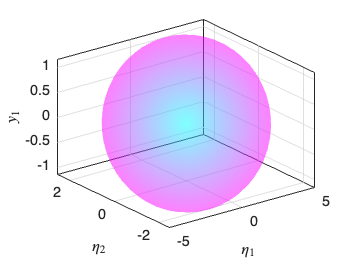


outdof = 1;
SSMOrder = 1;
IMInfo = IMGeometry(yData(indTrain,:), SSMDim, SSMOrder);
etaData = projectTrajectories(IMInfo, yData);
plotSSMWithTrajectories(IMInfo, outdof, yData(indTrain,:));

### Reduced-dynamics

Since the origin is of saddle-type, the linearized dynamics within the mixed-mode spectral subspace is characterized by a pair of real eigenvalues 


$$\lambda_2 <0<\lambda_1$$


and a pair of corresponding eigenvectors


$$e_{2\;} \;\textrm{and}\;e_1 \ldotp$$


ROMOrder = 11; 
% fitting the dynamics and 
RDInfo = IMDynamicsFlow(etaData(indTrain,:), ...
    'R_PolyOrd', ROMOrder);

Estimation of the reduced dynamics...  Done. 


[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yData);

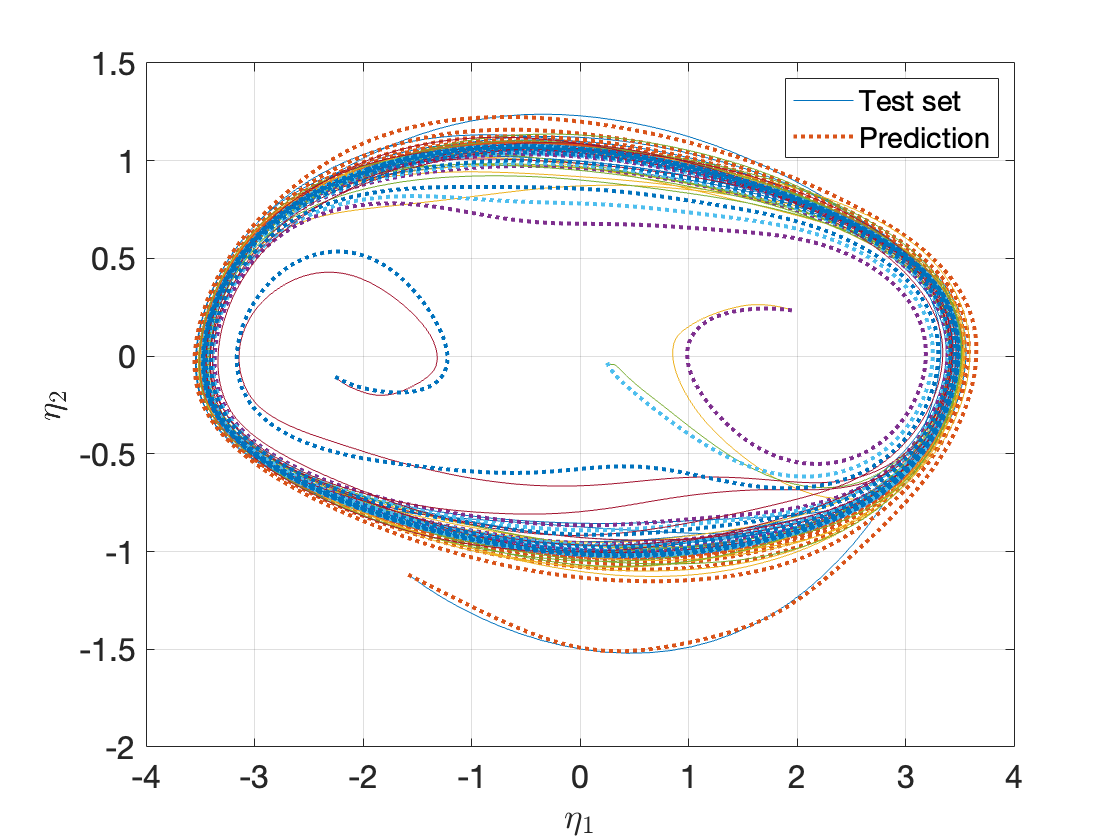

% visualizing the test set in the reduced coordinates
plotReducedCoordinates(etaData(indTest,:), etaRec(indTest,:))
legend({'Test set', 'Prediction'})


% the first block of the coefficient matrix is the linear part
% we compute now the eigenvectors of the origin of the reduced dynamics for
% later use
linearPart = RDInfo.reducedDynamics.coefficients(1:2, 1:2);
[~,Drd] = eig(linearPart);
Drd

Drd =        1.8624            0
            0      -2.0186


The eigenvalues are computed as 


$$\lambda_2 = -2.0186 \\
\lambda_1 = 1.8624 \\
$$


**Compare the prediction of the reduce order model and the test trajectory in the experiment**

plotTrajectories(yData(indTest,:), yRec(indTest,:), 'm', outdof,'Color', 'red')

### Drawing the reduced phase portrait

We now visualize the reduced dynamics restricted to the mixed-mode SSM by advecting a small sample of trajectories.

We select initial conditions on 

- The stable and unstable manifolds of the origin 

- The local unstable manifold of the spiral-type unstable fixed points

- The stable limit cycle

### Initial conditions on the unstable manifold

The origin is at $\eta =0$ and hence initial conditions close to the unstable and stable manifolds can be written as 


$${\textrm{IC}}_{\textrm{unstab}\ldotp } =\pm \delta \;e_1$$



$${\textrm{IC}}_{\textrm{stab}\ldotp } =\pm \delta \;e_2$$
 

for some small $\delta \;\ldotp$

### Drawing the reduced phase space

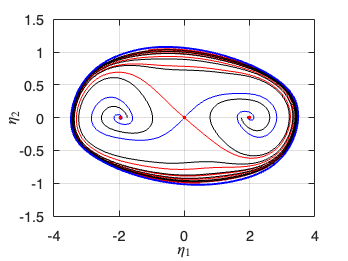

redDyn = RDInfo.reducedDynamics.map;
customFigure;
plot(0,0,'r.','MarkerSize',12)

uDir = 1; sDir = 2; tSim = 0:(0.033):20;
fixedPoints = [0; 0];
if real(RDInfo.eigenvaluesLinPartFlow(uDir))<0; uDir = 2; sDir = 1; end
% Integrate along the stable manifold in backward time
[~,etaSimt] = ode45(@(t,x) -redDyn(x),tSim,0.001*RDInfo.eigenvectorsLinPart(:,sDir));
plot(etaSimt(:,1),etaSimt(:,2),'b','Linewidth',1)
plot(etaSimt(end,1),etaSimt(end,2),'r.','MarkerSize',12)
fixedPoints = [fixedPoints transpose(etaSimt(end,:))];
[~,etaSimt] = ode45(@(t,x) -redDyn(x),tSim,-0.001*RDInfo.eigenvectorsLinPart(:,sDir));
plot(etaSimt(:,1),etaSimt(:,2),'b','Linewidth',1)
plot(etaSimt(end,1),etaSimt(end,2),'r.','MarkerSize',12)
fixedPoints = [fixedPoints transpose(etaSimt(end,:))];
% Integrate along the unstable manifold in forward time
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,0.001*RDInfo.eigenvectorsLinPart(:,uDir));
plot(etaSimt(:,1),etaSimt(:,2),'r','Linewidth',1)
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,-0.001*RDInfo.eigenvectorsLinPart(:,uDir));
plot(etaSimt(:,1),etaSimt(:,2),'r','Linewidth',1)
icLC = transpose(etaSimt(end,:));
% Other trajectories showing the transition
iCSym = [1.75; 0];
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,iCSym);
plot(etaSimt(:,1),etaSimt(:,2),'k','Linewidth',.5)
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,-iCSym);
plot(etaSimt(:,1),etaSimt(:,2),'k','Linewidth',.5)
% Plot Fixed point
plot(0,0,'r.','MarkerSize',12)
% Plot Limit cycle
[~,etaSimLC] = ode45(@(t,x) redDyn(x),0:(0.033):100,icLC);
[~,etaSimLC] = ode45(@(t,x) redDyn(x),0:(0.033):100,transpose(etaSimLC(end,:)));
plot(etaSimLC(:,1),etaSimLC(:,2),'b','Linewidth',2)
xlabel('$\eta_1$','interpreter','latex')
ylabel('$\eta_2$','interpreter','latex')

### Drawing the phase portrait in physical coordinates

We now visualize the dynamics back to the physical coordinates which are the tip displacement and tip velocity, by using a coordinate change.

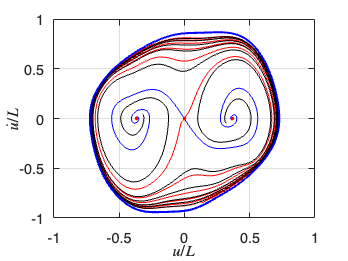

pos_u = 1;
vec_u = zeros(1,size(yData{1,2},1)); vec_u(pos_u) = 1;
redDyn = RDInfo.reducedDynamics.map;
W = IMInfo.parametrization.map;
DW = IMInfo.parametrization.tangentSpaceAtOrigin;
C = @(eta) [vec_u*W(eta); vec_u*DW*redDyn(eta)];

customFigure;
plot(0,0,'r.','MarkerSize',12)
% Integrate along the stable manifold in bw time
[~,etaSimt] = ode45(@(t,x) -redDyn(x),tSim,0.001*RDInfo.eigenvectorsLinPart(:,sDir));
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'b','Linewidth',1)
plot(xSimt(end,1),xSimt(end,2),'r.','MarkerSize',12)
[~,etaSimt] = ode45(@(t,x) -redDyn(x),tSim,-0.001*RDInfo.eigenvectorsLinPart(:,sDir));
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'b','Linewidth',1)
plot(xSimt(end,1),xSimt(end,2),'r.','MarkerSize',12)
% Integrate along the unstable manifold in fw time
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,0.001*RDInfo.eigenvectorsLinPart(:,uDir));
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'r','Linewidth',1)
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,-0.001*RDInfo.eigenvectorsLinPart(:,uDir));
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'r','Linewidth',1)
icLC = transpose(etaSimt(end,:));
% Other trajectories
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,iCSym);
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'k','Linewidth',.5)
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,-iCSym);
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'k','Linewidth',.5)
% Fixed point
plot(0,0,'r.','MarkerSize',12)
% Limit cycle
xSimLC = transpose(C(transpose(etaSimLC)));
plot(xSimLC(:,1),xSimLC(:,2),'b','Linewidth',2)
xlabel('$u/L$','interpreter','latex')
ylabel('$\dot{u}/L$','interpreter','latex')

## Fitting the reduced-order model at High $\textrm{Re}={10}^5$

We repeat the same analysis as in low Reynolds numbers. First we repeat the manifold fitting that we look for a 2-D manifold attached to the unstable middle fixed point, as it is still of saddle type.

We look for a polynomial parametrization of this SSM in the delay-embedded observable space as we have shown in the low Reynolds number case. We then plot the fitted manifold as well as trajectories.

load("HighReData.mat")
indTrain = 1:13;
indTest = 14:17;
SSMDim = 2;
overEmbed = 4;
[yData, ~] = coordinatesEmbedding(xData_high, SSMDim, 'OverEmbedding', overEmbed);

The 9 embedding coordinates consist of the measured state and its 8 time-delayed measurements.


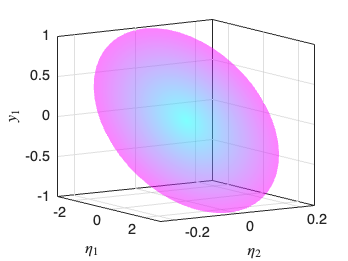


SSMOrder = 1;
IMInfo = IMGeometry(yData(indTrain,:), SSMDim, SSMOrder);
plotSSMWithTrajectories(IMInfo, outdof, yData(indTrain,:));
view([56.35 10.59])

Then we seek for a polynomial parametrization for the reduced dynamics restricted to the manifold. We then evaluate the reduced dynamics by comparing the prediction and the test experimental trajectories.

etaData = projectTrajectories(IMInfo, yData);
ROMOrder = 11;
RDInfo = IMDynamicsFlowParaCon(etaData(indTrain,:), 'Rs_PolyOrd', ROMOrder, 'style', 'none');

Estimation of the reduced dynamics...  Done. 


[yRec, ~, ~] = advect(IMInfo, RDInfo, yData);

### Drawing the reduced phase space for high Re

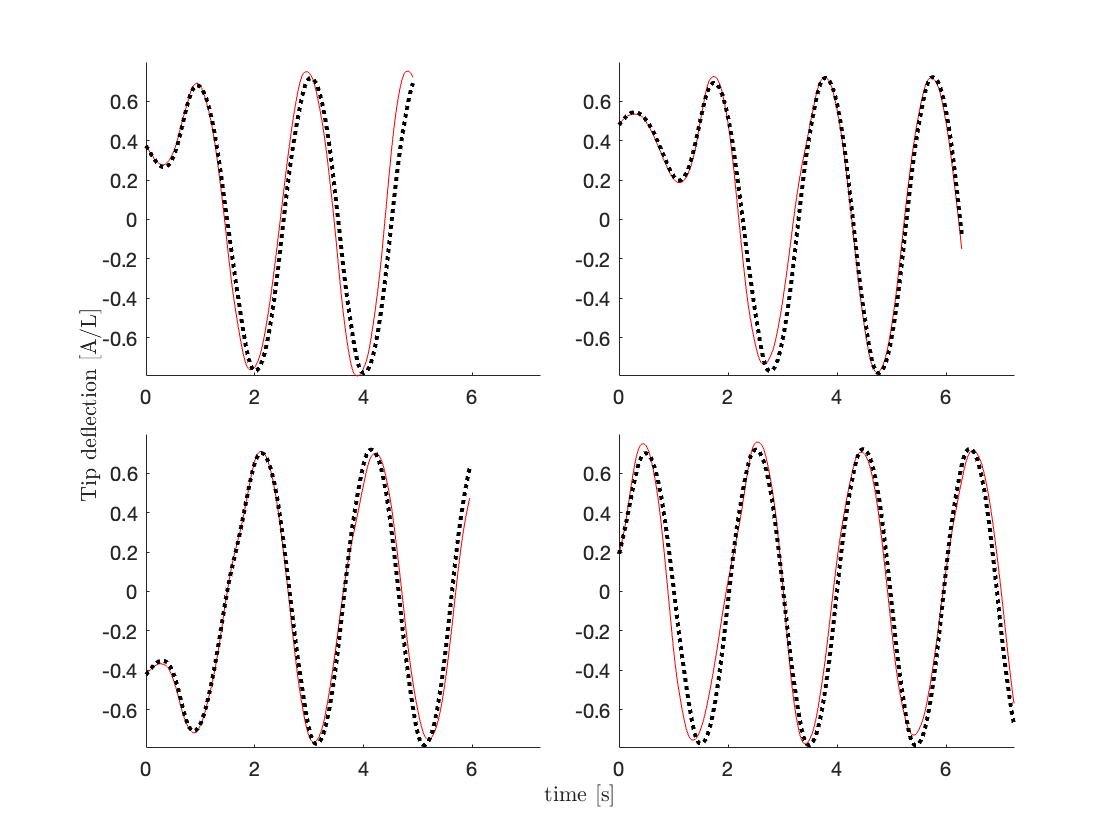

redDyn = RDInfo.reducedDynamics.map;
DxredDyn = RDInfo.reducedDynamics.jacobianState;
[Vrd,Drd] = eig(DxredDyn([0; 0]));
RDInfo.eigenvaluesLinPartFlow = diag(Drd);
RDInfo.eigenvectorsLinPart = Vrd;
%% Set x = [u du_dt], we now find the map x = C(eta). We assume parametrization of order 1
pos_u = 1;
vec_u = zeros(1,size(yData{1,2},1)); vec_u(pos_u) = 1;
W = IMInfo.parametrization.map;
DW = IMInfo.parametrization.tangentSpaceAtOrigin;
C = @(eta) [vec_u*W(eta); vec_u*DW*redDyn(eta)];
%%
fullTrajDist = computeTrajectoryErrors(yRec, yData);
plotTrajectories(yData(indTest,:), yRec(indTest,:), 'm', outdof,'Color', 'red')
xlabel('time [s]')
ylabel('Tip deflection [A/L]')

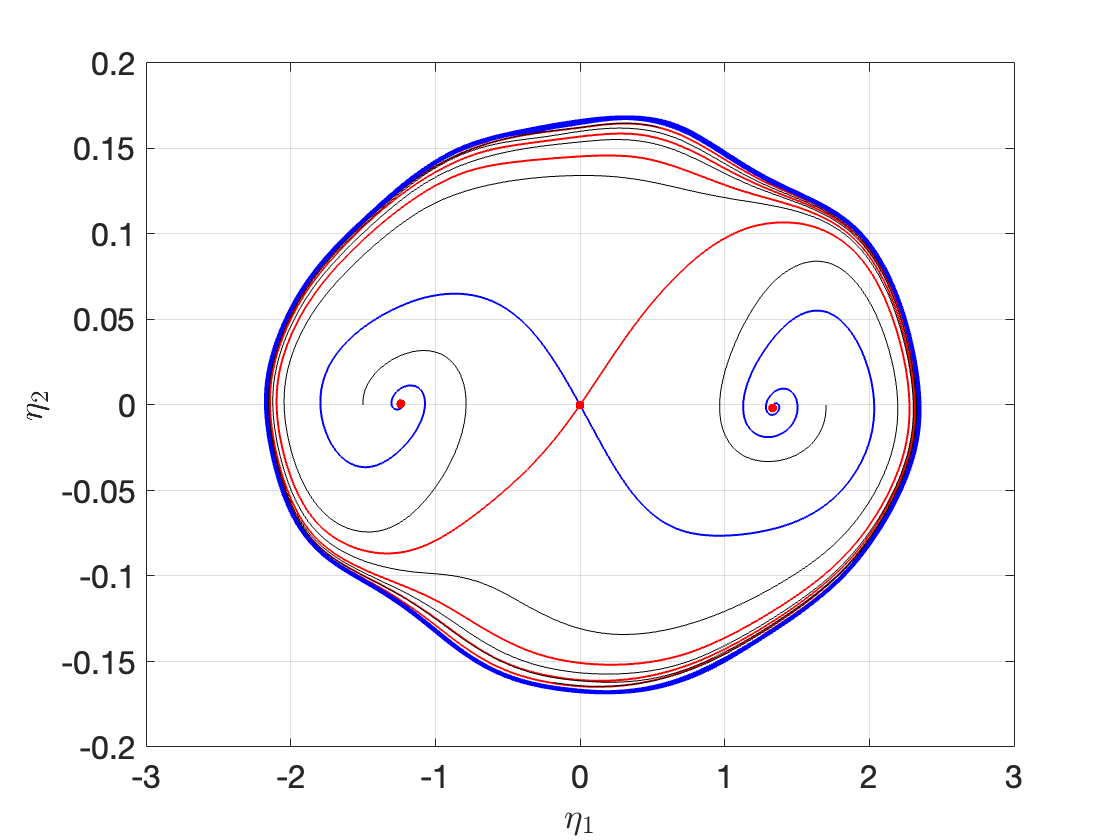

%% reduced phase space
customFigure;
plot(0,0,'r.','MarkerSize',12)

uDir = 1; sDir = 2; tSim = 0:(0.033/4):5;
fixedPoints = [0; 0];
if real(RDInfo.eigenvaluesLinPartFlow(uDir))<0; uDir = 2; sDir = 1; end
% Integrate along the stable manifold in bw time
[~,etaSimt] = ode45(@(t,x) -redDyn(x),tSim,0.001*RDInfo.eigenvectorsLinPart(:,sDir));
plot(etaSimt(:,1),etaSimt(:,2),'b','Linewidth',1)
plot(etaSimt(end,1),etaSimt(end,2),'r.','MarkerSize',12)
fixedPoints = [fixedPoints transpose(etaSimt(end,:))];
[~,etaSimt] = ode45(@(t,x) -redDyn(x),tSim,-0.001*RDInfo.eigenvectorsLinPart(:,sDir));
plot(etaSimt(:,1),etaSimt(:,2),'b','Linewidth',1)
plot(etaSimt(end,1),etaSimt(end,2),'r.','MarkerSize',12)
fixedPoints = [fixedPoints transpose(etaSimt(end,:))];
% Integrate along the unstable manifold in fw time
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,0.001*RDInfo.eigenvectorsLinPart(:,uDir));
plot(etaSimt(:,1),etaSimt(:,2),'r','Linewidth',1)
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,-0.001*RDInfo.eigenvectorsLinPart(:,uDir));
plot(etaSimt(:,1),etaSimt(:,2),'r','Linewidth',1)
icLC = transpose(etaSimt(end,:));
% Other trajectories
iCSym = [1.7; 0];
%iCSym = [0; 0.1];
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,iCSym);
plot(etaSimt(:,1),etaSimt(:,2),'k','Linewidth',.5)
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,-[1.5;0]);
plot(etaSimt(:,1),etaSimt(:,2),'k','Linewidth',.5)
% Fixed point
plot(0,0,'r.','MarkerSize',12)
% Limit cycle
[~,etaSimLC] = ode45(@(t,x) redDyn(x),0:(0.033):30,icLC);
[~,etaSimLC] = ode45(@(t,x) redDyn(x),0:(0.033/4):5,transpose(etaSimLC(end,:)));
plot(etaSimLC(:,1),etaSimLC(:,2),'b','Linewidth',2)
xlabel('$\eta_1$','interpreter','latex')
ylabel('$\eta_2$','interpreter','latex')

### Drawing the phase portrait in physical coordinates for high Re

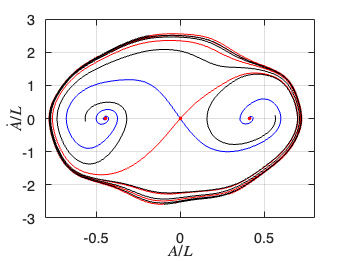

customFigure;
plot(0,0,'r.','MarkerSize',12)
% Integrate along the stable manifold in bw time
[~,etaSimt] = ode45(@(t,x) -redDyn(x),tSim,0.001*RDInfo.eigenvectorsLinPart(:,sDir));
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'b','Linewidth',1)
plot(xSimt(end,1),xSimt(end,2),'r.','MarkerSize',12)
[~,etaSimt] = ode45(@(t,x) -redDyn(x),tSim,-0.001*RDInfo.eigenvectorsLinPart(:,sDir));
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'b','Linewidth',1)
plot(xSimt(end,1),xSimt(end,2),'r.','MarkerSize',12)
% Integrate along the unstable manifold in fw time
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,0.001*RDInfo.eigenvectorsLinPart(:,uDir));
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'r','Linewidth',1)
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,-0.001*RDInfo.eigenvectorsLinPart(:,uDir));
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'r','Linewidth',1)
icLC = transpose(etaSimt(end,:));
% Other trajectories
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,iCSym);
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'k','Linewidth',.5)
[~,etaSimt] = ode45(@(t,x) redDyn(x),tSim,-iCSym);
xSimt = transpose(C(transpose(etaSimt)));
plot(xSimt(:,1),xSimt(:,2),'k','Linewidth',.5)
% Fixed point
plot(0,0,'r.','MarkerSize',12)
% Limit cycle
xSimLC = transpose(C(transpose(etaSimLC)));
plot(xSimLC(:,1),xSimLC(:,2),'b','Linewidth',2)
xlabel('$A/L$','interpreter','latex')
ylabel('$\dot{A}/L$','interpreter','latex')
xlim([-0.8 0.8])